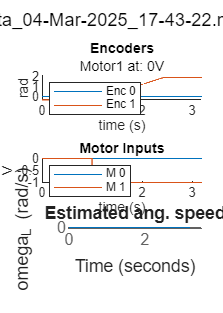

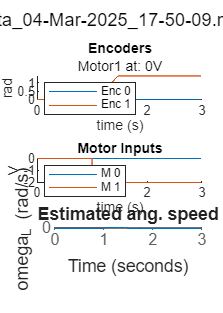

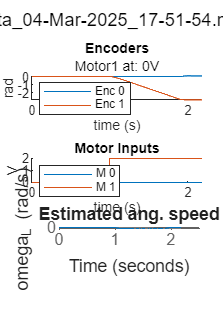

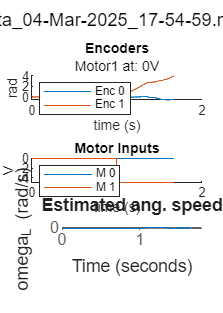

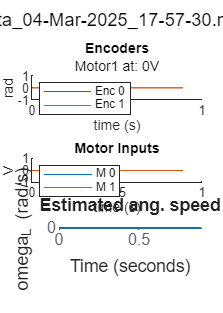

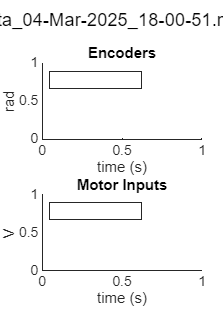

Output argument "isProper" (and possibly others) not assigned a value in the execution with "smartPlotEncVoltage" function.

filelist = ["data_04-Mar-2025_10.mat","data_04-Mar-2025_14-46-39.mat","data_04-Mar-2025_14-48-35.mat","data_04-Mar-2025_14-49-36.mat","data_04-Mar-2025_15-02-19.mat","data_04-Mar-2025_15-04-28.mat","data_04-Mar-2025_15-06-09.mat","data_04-Mar-2025_15-07-04.mat","data_04-Mar-2025_15-13-13.mat","data_04-Mar-2025_15-16-08.mat","data_04-Mar-2025_15-27-48.mat","data_04-Mar-2025_15-29-27.mat","data_04-Mar-2025_15-30-56.mat","data_04-Mar-2025_15-31-20.mat","data_04-Mar-2025_15-33-26.mat","data_04-Mar-2025_15-34-00.mat","data_04-Mar-2025_15-37-14.mat","data_04-Mar-2025_15-39-43.mat","data_04-Mar-2025_15-42-28.mat","data_04-Mar-2025_15-43-46.mat","data_04-Mar-2025_15-47-42.mat","data_04-Mar-2025_15-49-10.mat","data_04-Mar-2025_15-51-30.mat","data_04-Mar-2025_15-52-22.mat","data_04-Mar-2025_15-54-09.mat","data_04-Mar-2025_15-57-04.mat","data_04-Mar-2025_16-08-14.mat","data_04-Mar-2025_16-11-22.mat","data_04-Mar-2025_16-14-18.mat","data_04-Mar-2025_16-16-56.mat","data_04-Mar-2025_16-18-18.mat","data_04-Mar-2025_16-21-30.mat","data_04-Mar-2025_16-24-24.mat","data_04-Mar-2025_16-29-52.mat","data_04-Mar-2025_16-55-40.mat","data_04-Mar-2025_17-24-37.mat","data_04-Mar-2025_17-40-31.mat","data_04-Mar-2025_17-41-21.mat","data_04-Mar-2025_17-43-22.mat","data_04-Mar-2025_17-50-09.mat","data_04-Mar-2025_17-51-54.mat","data_04-Mar-2025_17-54-59.mat","data_04-Mar-2025_17-57-30.mat","data_04-Mar-2025_17-57-53.mat","data_04-Mar-2025_18-00-51.mat","data_04-Mar-2025_18-01-13.mat","data_04-Mar-2025_18-03-09.mat","data_04-Mar-2025_18-06-22.mat","data_04-Mar-2025_18-07-09.mat","data_04-Mar-2025_18-09-15.mat","data_04-Mar-2025_18-10-36.mat","data_04-Mar-2025_18-11-39.mat","data_04-Mar-2025_18-12-13.mat","data_04-Mar-2025_18-13-24.mat","data_04-Mar-2025_18-14-40.mat","data_04-Mar-2025_18-15-39.mat","data_04-Mar-2025_18-16-46.mat","data_04-Mar-2025_18-17-52.mat","data_04-Mar-2025_18-18-49.mat"];
% 
% n_exp = 54;
% load("lab1/data/"+filelist(n_exp),"data")
%plot(data(1,:),data(2,:))
% smartPlotEncVoltage(data,filelist(n_exp))

filetitle = "trash/"+string(datetime(now, 'ConvertFrom', 'datenum','Format','yyyy-MM-dd HH+mm+ss'));


for n_exp = 39:(size(filelist,2))

    load("lab1/data/"+filelist(n_exp),"data");
    if n_exp>=38
        fil = true;
    else 
        fil = false;
    end
    res = smartPlotEncVoltage(data,filelist(n_exp),fil);
    if res
        f = gcf;
        exportgraphics(f,filetitle+".pdf",'ContentType','vector','Append',true);
    end
end